# ISONE hourly bid and demand data analysis

## Import ISONE hourly bid data

% Import ISONE hourly bid data in 2019 whole year
% Run this under the model_code directory or change the genFileDir manually
bidFileDir = "..\data\2019_DAM_BID_ISONE\";
% bidFileName = "hbdayaheadenergyoffer_2019*.csv";
% bidDataStore = fileDatastore(bidFileDir + bidFileName, "ReadFcn", @importBidISONE, "UniformRead", true);
% bidAll = readall(bidDataStore);

hourlyBid = importBidISONE(bidFileDir + "hbdayaheadenergyoffer_20190101.csv");

participantIDs = unique(hourlyBid.ParticipantID);
assetIDs = unique(hourlyBid.AssetID);
groupsummary(hourlyBid, ["ParticipantID"])

ans = 81×2 table
    ParticipantID    GroupCount
    _____________    __________

       124454            24    
       126216            48    
       172623            24    
       172669            72    
       173252            72    
       184983            48    
       188321            48    
       196063            72    
       206845           408    
       20721             48    
       212494           144    
       219842            24    
       292445           408    
       295534            24    
       331313            72    
       355376            48    


## Import ISONE hourly demand data

% Import hourly generation data of generators in RGGI database in the 2019 whole year
% Run this under the model_code directory or change the genFileDir manually
demandFileDir = "..\data\2019_DEMAND_ISONE\";
demandFileName = "da_hourlydemand_2019*.csv";
demandDataStore = fileDatastore(demandFileDir + demandFileName, "ReadFcn", @importDemandISONE, "UniformRead", true);
demandAll = readall(demandDataStore);

hourlyDemand01 = demandAll(demandAll.Date == '01/01/2019', :)

hourlyDemand01 = 24×4 table
       Date       Hour    DayAheadDemand         DateTime      
    __________    ____    ______________    ___________________

    01/01/2019      1         10343         01/01/2019 01:00:00
    01/01/2019      2         10026         01/01/2019 02:00:00
    01/01/2019      3         10026         01/01/2019 03:00:00
    01/01/2019      4         10176         01/01/2019 04:00:00
    01/01/2019      5         10275         01/01/2019 05:00:00
    01/01/2019      6         10393         01/01/2019 06:00:00
    01/01/2019      7         10815         01/01/2019 07:00:00
    01/01/2019      8         11183         01/01/2019 08:00:00
    01/01/2019      9         11762         01/01/2019 09:00:00
    01/01/2019     10         12089         01/01/2019 10:00:00
    01/01/2019     11         12199         01/01/2019 11:00:00
   

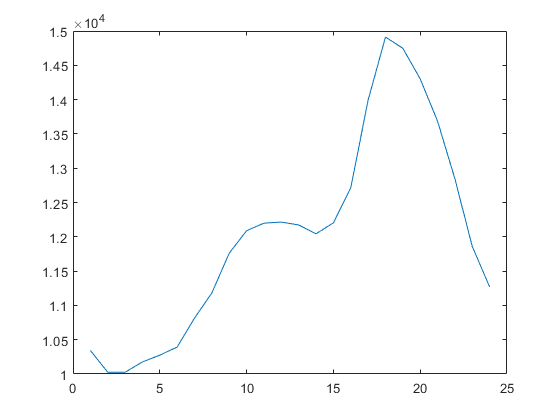

plot(hourlyDemand01.DayAheadDemand)

## Calculate aggregate supply function

selHour = 12;
% Obtain total demand at the selected hour
selHourDemand = hourlyDemand01(hourlyDemand01.Hour == selHour, :).DayAheadDemand;
% Obtain bids at the selected hour
allBids = hourlyBid(hourlyBid.Hour == selHour, :);
allBids = removevars(allBids, ["Date", "Hour", "MustTakeEnergy", "MaximumDailyEnergyAvailable", "EconomicMaximum", "EconomicMinimum", ...
    "ColdStartupPrice", "IntermediateStartupPrice", "HotStartupPrice", "NoLoadPrice"]);
allBids = movevars(allBids, "UnitStatus", "After", "AssetID");
allBids = movevars(allBids, "DateTime", "Before", "ParticipantID");
% remove unavailable units, left with economic and must-run units
availBids = allBids(allBids.UnitStatus ~= "UNAVAILABLE", :);

% Stack all bids together 
seg1 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment1Price", "Segment1MW"]));
seg2 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment2Price", "Segment2MW"]));
seg3 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment3Price", "Segment3MW"]));
seg4 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment4Price", "Segment4MW"]));
seg5 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment5Price", "Segment5MW"]));
seg6 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment6Price", "Segment6MW"]));
seg7 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment7Price", "Segment7MW"]));
seg8 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment8Price", "Segment8MW"]));
seg9 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment9Price", "Segment9MW"]));
seg10 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment10Price", "Segment10MW"]));
stackedBids = cell2table([seg1; seg2; seg3; seg4; seg5; seg6; seg7; seg8; seg9; seg10], ...
    "VariableNames", ["ParticipantID", "AssetID", "SegmentPrice", "SegmentMW"]);
% Remove NA bids
stackedBids = rmmissing(stackedBids);
% Sort bids by price from lowest to highest
stackedBids = sortrows(stackedBids, "SegmentPrice", "ascend");
% Calculate cumulative bid quantity
stackedBids.CumsumMW = cumsum(stackedBids.SegmentMW)

stackedBids = 756×5 table
    ParticipantID    AssetID    SegmentPrice    SegmentMW    CumsumMW
    _____________    _______    ____________    _________    ________

       124454         57942         -150           0.1          0.1  
       384652         55290         -150             6          6.1  
       399648         42103         -150             8         14.1  
       399648         46072         -150             3         17.1  
       399648         77213         -150            13         30.1  
       399648         87105         -150            32         62.1  
       399648         97130         -150            30         92.1  
       412080         15908         -150            15        107.1  
       475203         52500         -150             2        109.1  
       547098         63551      

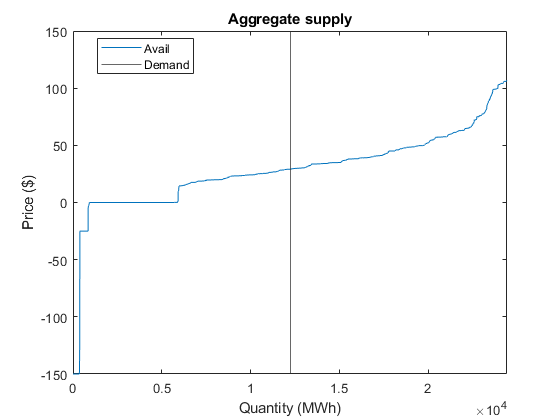

figure;
hold on;
plot(stackedBids.CumsumMW, stackedBids.SegmentPrice)
xline(selHourDemand);
hold off; box on;
legend(["Avail", "Demand"], "Location", "best");
title("Aggregate supply");
xlabel("Quantity (MWh)");
ylabel("Price ($)");
xlim([0, 2*selHourDemand]);